# Visualizing Model Complexity

## From Model to Table

The first and most important thing is to create a table that holds information about all the Simulink models. 

% Open the required Simulink models
models = {'Perception', 'Planning', 'Control', 'Simulation'};
open_system(models);

% Create a table to store information about Simulink models
T = table();
for i = 1:length(models)
    T = modelToTable(T, models{i});
end

% OPTIONAL: Purge elements with less blocks than `lim`
lim = 1;
T(T.Weight<lim,:) = [];

% Display the table
disp(T);

                                                                                                                                    EndNodes                                                                                                                                     Weight
    _________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________    ______

    "Perception"                                                                                                                 "Perception/Object Detection Annotater"                                                                                                             8 
    "Perception"                                                                           

## From Table to Sankey

Once the table is availabe, the Sankey diagram can be generated:

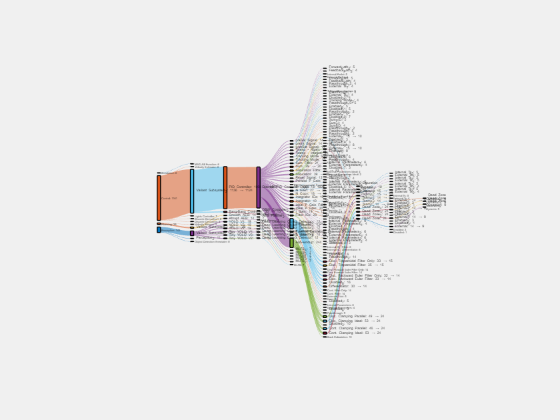

% Create a graph with directed edges from the table
DG = digraph(T);
f = uifigure;

% Create a Sankey chart edges from the directed graph
SC = SankeyChart("Parent", f, "GraphData", DG);
SC.LabelIncludeTotal = "on";
SC.NodeFontSize = 2;
SC = fixBlockNames(SC);